# Flux Balance Analysis

## Author(s): Ronan M.T. Fleming, Leiden University

## Reviewer(s):

## INTRODUCTION

In this practical, the use of Flux Balance Analysis (FBA) is introduced using the E. coli core model, with functions in the COBRA Toolbox v3.0 [2].  

Flux balance analysis is a solution to the optimisation problem


$$
\begin{array}{ll}
\textrm{max} & c^{T}v\\
\text{s.t.} & Sv=b\\
 & l\leq v\leq u
\end{array}
\end{equation}$$


where $c$ is a vector of linear objective coefficients, $S$ is an m times n matrix of stoichiometric coefficients for m molecular species involved in n reactions. $l\;\textrm{and}\;u\;$are n times 1 vectors that are the lower and upper bounds on the n times 1 variable vector $v\;$of reaction rates (fluxes). The optimal objective value is $c^{T}v^{\star}$  is always unique, but the optimal vector $v^{\star}$ is usually not unique.

In summary, the data is {c,S,l,u} and the variable being optimised is v.

## TIMING

*< 1 hrs*

## E. coli core model

A map of the E. coli core model is shown in Figure 1. 

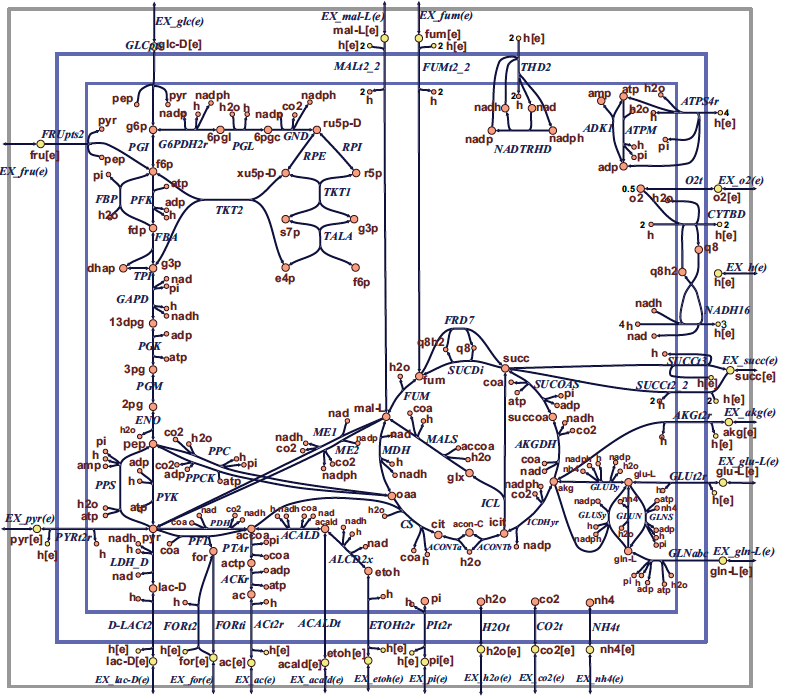

**Figure 1**  **Map of the core E. coli metabolic network. ** Orange circles represent cytosolic metabolites, yellow circles represent extracellular metabolites, and the blue arrows represent reactions.  Reaction name abbreviations are uppercase (blue) and metabolite name abbreviations are lowercase (rust colour).  This flux map was drawn using SimPheny and edited for clarity with Adobe Illustrator. 

## MATERIALS - EQUIPMENT SETUP

Please ensure that all the required dependencies (e.g. , `git` and `curl`) of The COBRA Toolbox have been properly installed by following the installation guide [here](https://opencobra.github.io/cobratoolbox/stable/installation.html). Please ensure that the COBRA Toolbox has been initialised (tutorial_initialize.mlx) and verify that the pre-packaged LP and QP solvers are functional (tutorial_verify.mlx).

## PROCEDURE

## Load E. coli core model

The most appropriate way to load a model into The COBRA Toolbox is to use the `readCbModel` function. 

fileName = 'ecoli_core_model.mat';
if ~exist('modelOri','var')
    modelOri = readCbModel(fileName);
end
%backward compatibility with primer requires relaxation of upper bound on
%ATPM
modelOri = changeRxnBounds(modelOri,'ATPM',1000,'u');
model = modelOri;

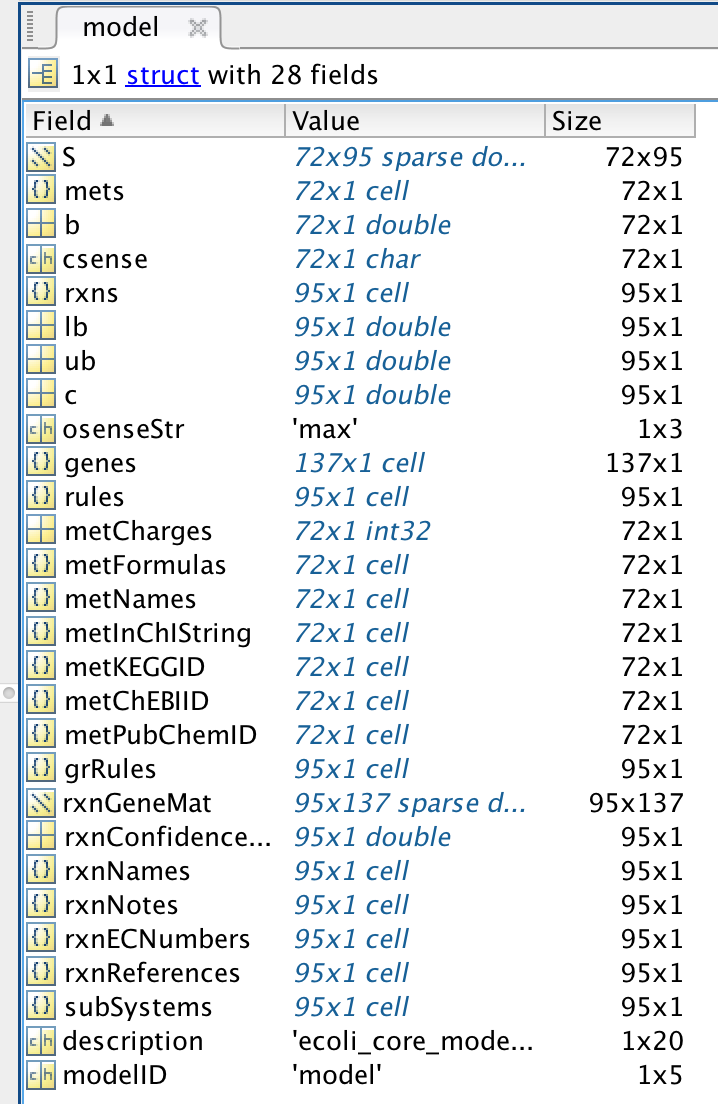

The meaning of each field in a standard model is defined in the [standard COBRA model field definition](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/notes/COBRAModelFields.md).

In general, the following fields should always be present: 

- **S**, the stoichiometric matrix

- **mets**, the identifiers of the metabolites

- **b**, Accumulation (positive) or depletion (negative) of the corresponding metabolites. 0 Indicates no concentration change.

- **csense**, indicator whether the b vector is a lower bound ('G'), upper bound ('L'), or hard constraint 'E' for the metabolites.

- **rxns**, the identifiers of the reactions

- **lb**, the lower bounds of the reactions

- **ub**, the upper bounds of the reactions

- **c**, the linear objective

- **genes**, the list of genes in your model 

- **rules**, the Gene-protein-reaction rules in a computer readable format present in your model.

- **osenseStr**, the objective sense either `'max'` for maximisation or `'min'` for minimisation

## Checking the non-trivial constraints on a model

#### What are the default constraints on the model? 

#### Hint: `printConstraints`

## Example 1: Calculating growth rates

Growth of E. coli on glucose can be simulated under aerobic conditions.  

#### What is the growth rate of *E. coli *on glucose (uptake rate = 18.5 mmol/gDW/h) under aerobic conditions?  

#### Hint: `changeRxnBounds`, `changeObjective`, `optimizeCbModel`, `printFluxVector`

#### What are the main fields to check in the FBAsolution structure?

#### Hint: `help optimizeCbModel`

#### What does FBAsolution.stat mean?

## Example 2: Display an optimal flux vector on a metabolic map

#### Which reactions/pathways are in use (look at the flux vector and flux map)?

#### Hint: `drawFlux`

if exist('FBAsolution','var')
    outputFormatOK = changeCbMapOutput('matlab');
    map=readCbMap('ecoli_core_map');
    options.zeroFluxWidth = 0.1;
    options.rxnDirMultiplier = 10;
    drawFlux(map, model, FBAsolution.v, options);
end

## Example 3:  Anerobic growth

Growth of E. coli on glucose can be simulated under anaerobic conditions.  

#### What is the optimal growth rate under anaerobic conditions?

#### Hint: changeRxnBounds

#### What reactions of oxidative phosphorylation are active in anaerobic conditions?

#### Hint: `printFluxVector` `drawFlux`

## Example 4:  Growth on alternate substrates

Just as FBA was used to calculate growth rates of E. coli on glucose, it can also be used to simulate growth on other substrates.  The core E. coli model contains exchange reactions for 13 different organic compounds, each of which can be used as the sole carbon source under aerobic conditions. 

#### What is the growth rate of *E. coli *on succinate?

#### Hint: `changeRxnBounds`

## REFERENCES

1. Orth, J.D., Fleming, R.M. & Palsson, B.O. in EcoSal - Escherichia coli and Salmonella Cellular and Molecular Biology. (ed. P.D. Karp) (ASM Press, Washington D.C.; 2009).

2. Varma, A. & Palsson, B.O. Metabolic capabilities of Escherichia coli: I. Synthesis of biosynthetic precursors and cofactors. Journal of Theoretical Biology 165, 477-502 (1993).

3. Laurent Heirendt & Sylvain Arreckx, Thomas Pfau, Sebastian N. Mendoza, Anne Richelle, Almut Heinken, Hulda S. Haraldsdottir, Jacek Wachowiak, Sarah M. Keating, Vanja Vlasov, Stefania Magnusdottir, Chiam Yu Ng, German Preciat, Alise Zagare, Siu H.J. Chan, Maike K. Aurich, Catherine M. Clancy, Jennifer Modamio, John T. Sauls, Alberto Noronha, Aarash Bordbar, Benjamin Cousins, Diana C. El Assal, Luis V. Valcarcel, Inigo Apaolaza, Susan Ghaderi, Masoud Ahookhosh, Marouen Ben Guebila, Andrejs Kostromins, Nicolas Sompairac, Hoai M. Le, Ding Ma, Yuekai Sun, Lin Wang, James T. Yurkovich, Miguel A.P. Oliveira, Phan T. Vuong, Lemmer P. El Assal, Inna Kuperstein, Andrei Zinovyev, H. Scott Hinton, William A. Bryant, Francisco J. Aragon Artacho, Francisco J. Planes, Egils Stalidzans, Alejandro Maass, Santosh Vempala, Michael Hucka, Michael A. Saunders, Costas D. Maranas, Nathan E. Lewis, Thomas Sauter, Bernhard Ø. Palsson, Ines Thiele, Ronan M.T. Fleming, **Creation and analysis of biochemical constraint-based models: the COBRA Toolbox v3.0**, Nature Protocols, volume 14, pages 639–702, 2019 [doi.org/10.1038/s41596-018-0098-2](https://doi.org/10.1038/s41596-018-0098-2).